# 1.2.19. Обработка аудиосигнала

Файл, содержащий аудио-данные называется *chaykovsky_sine.wav*. Имопртируйте аудио-данные командой *audioread.  *Запишите отсчёты аудиосигнала в переменную *x*, а частоту дискретизации - в переменную *fs*.

[x,fs] = audioread('chaykovsky_sine.wav');

Послушайте первые 10 секунд аудио-файла. Обратите внимание на неприятный свист. Можем ли мы определить источник этого свиста на графике сигнала во времени?

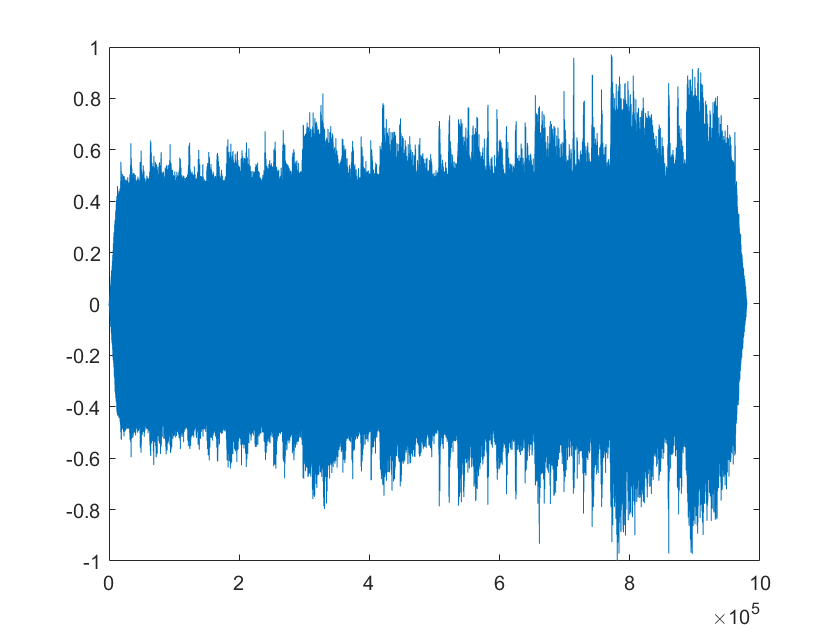

sound(x,fs);
pause(10);
clear sound;
plot(x);

### Спектральный анализ сигнала:

Воспользуйтесь функцией *periodogram* для оценки спектральной плотности мощности сигнала. Вызовите эту функцию с двумя выходными аргументами. Первый выход функции запишите в переменную *pxx*, второй - в переменную *fx*. Передайте функции в качетсве первого входного аргумента сигнал x, второй аргумент оставьте пустым (необходимо передать пустой массив - []), в качестве третьего аргумента передайте количество точек выходного вектора - 2^16, а четвёртым аргументом передайте чатоту дискретизации аудиосигнала. 

[pxx,fx] = periodogram(x,[],2^16,fs);

Запишите в переменную *logpxx* отсчёты спектральной плотности мощности в логарифмической шкале. 

logpxx = 10*log10(pxx);

Отобразите на графике зависимость спектральной плотности мощности от частоты в логарифмической шкале:

plot(fx,logpxx);
hold on;

Определите максимальное значение вектора logpxx, а также индекс этого значения. Максимальное значение запишите в переменную *max*, индекс - в переменную *maxidx*. 

[max,maxidx] = max(logpxx);

Определите значение частоты (вектор f), соответствующее максимальному значению вектора *logpxx*. Запишите это значение в переменную *fmax*.

fmax = fx(maxidx);

Отразите максимальное значение на графике спектральной плотности мощности красной точной.

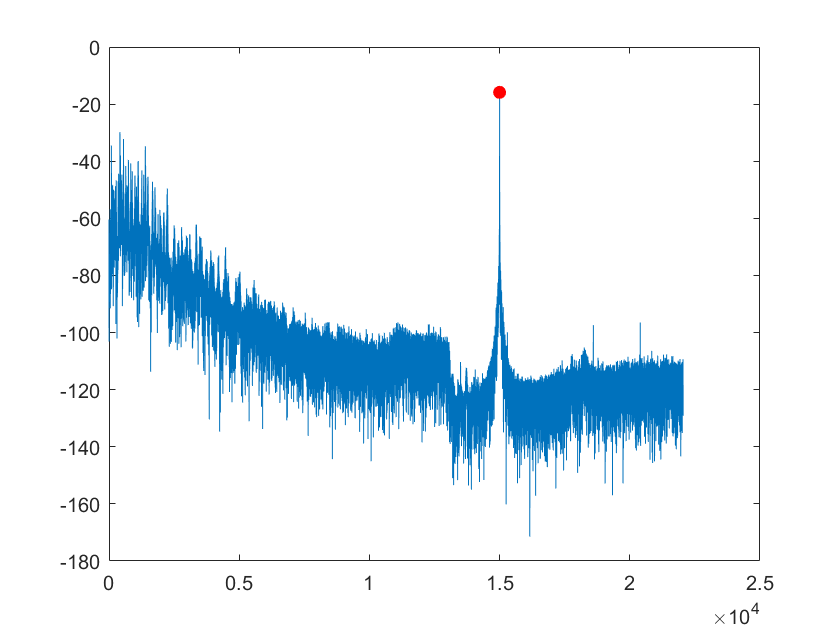

plot(fmax,max,'ro','MarkerFaceColor','red');

## Фильтрация:

Коэффициенты фильтра записаны в файле notch.mat. Загрузите коэффициенты в рабочее пространство.

load notch;

Воспользуйтесь командой *filter* для фильтрации исходного вектора *x*. Передайте команде в качестве аргументов последовательно коэффициенты числителя передаточной функции, затем коэффициенты знаменателя, и затем сигнал *x*.

y = filter(Num, Den, x);

Выполните спектральный анализ сигнала y по аналогии с сигналом *х*. Запишите векто значений спектральной плотности мощности в переменную *pxy*, а вектор значений частоты - в переменную *fy*.

[pxy,fy] = periodogram(y,[],2^16,fs);

Запишите в переменную *logpxy* отсчёты спектральной плотности мощности в логарифмической шкале. 

logpxy = 10*log10(pxy);

Отразите её на одном графике с исходной СПМ сигнала *х*.

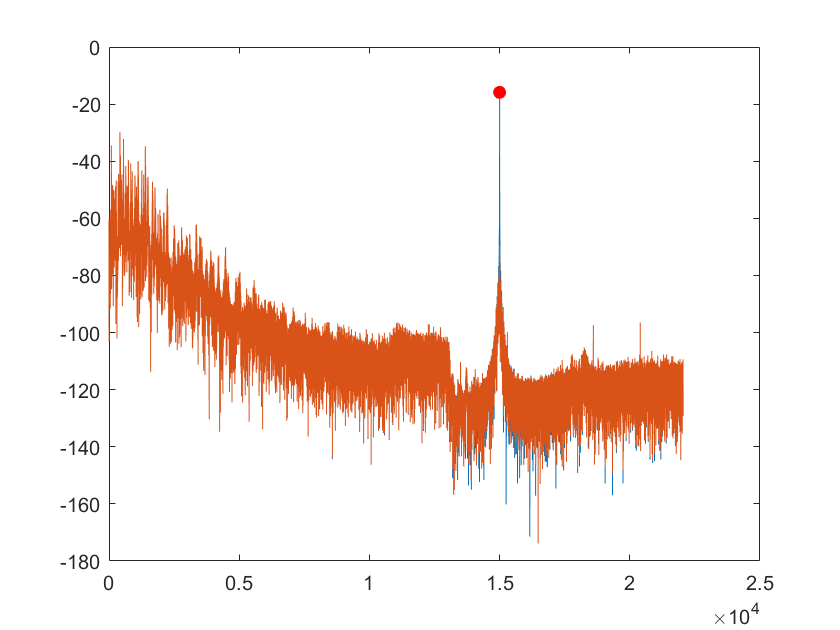

plot(fy,logpxy);
hold off;

Послушайте сигнал для проверки.

soundsc(y,fs);
pause(10);
clear sound;